Passo a passo do projeto do compensador de atraso de fase

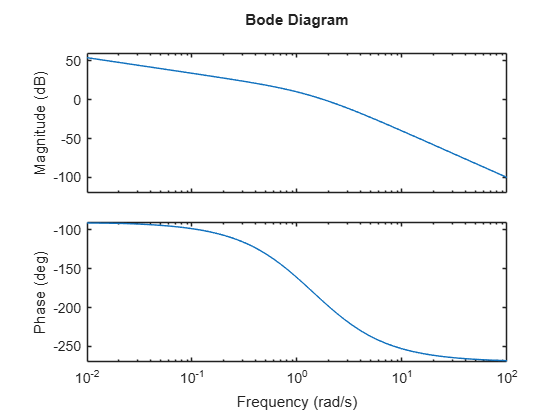

% Determinar o K conforme o erro de posição ou de velocidade
% Correçao da margem de fase: 
   % -180 + Margem requerida + acrescimo é a fase associada a nova
   % frequencia de cruzamento de ganho (wg') desejada
% Frequencia de corte escolhida por 1/T e wg'/10 com uma decada atras para
% garantir a estabilização da atenuação em zero.


s = tf('s');

G = 1/(s*(s+1)*(0.5*s+1));
% Kv = 5, aplicar o limite na funçao G;
% Margem de fase de ao menos 40°
% Margem de ganho de ao menos 10db

K = 5;
Gl = K*G;
bode(Gl)

% wg encontrado = 1.81 rad/s
phi = -180 + 40 + 10

phi = -130

% wg' para o novo phi = 130° -> 0.489
wgi = 0.489; % com ganho de 19.1

T = 10/wgi

T = 20.4499

a = 10^(19.1/20)

a = 9.0157

a*T

ans = 184.3704


% Montar o compensador 

Gc = (K*(T*s+1))/(a*T*s+1)


Gc =
 
  102.2 s + 5
  -----------
  184.4 s + 1
 
Continuous-time transfer function.


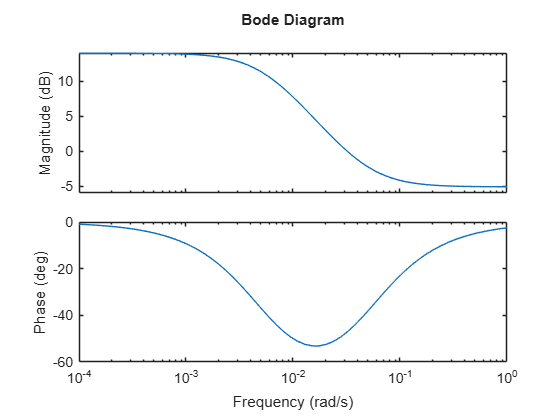

bode(Gc)

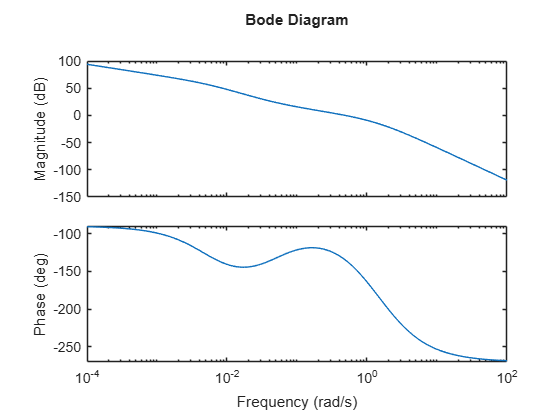

bode(Gc*G)

step(feedback(G,1))
hold

Current plot held


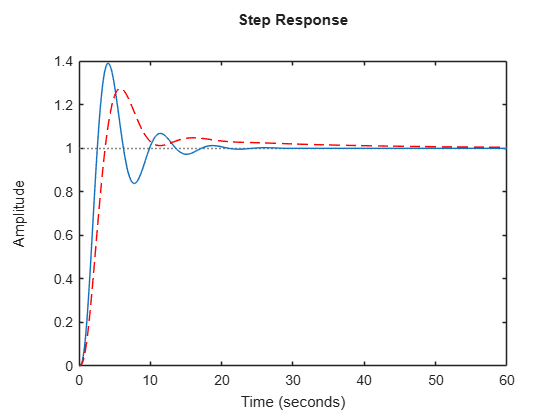

step(feedback(Gc*G,1),'--red')